Noise is just another function that is combined with the original image function to get a new function

Multiplying a bunch of random numbers generated from a Gaussian or Normal distribution changes their effective standard deviation, i.e. how far apart the values are spread.

Gaussian noise

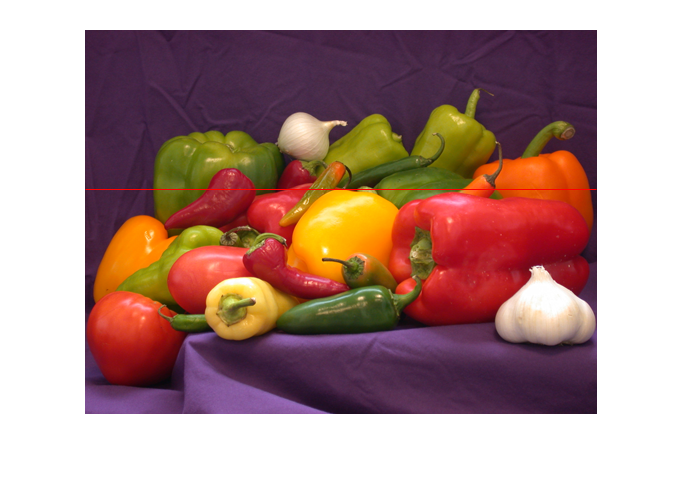

im = imread('peppers.png');
imshow(im)
line([1 512],[160 160],'color','r')

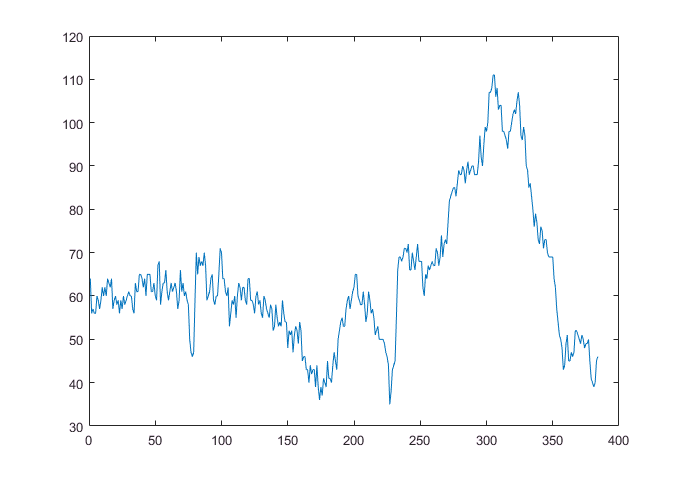

% plot on the red layer
plot(im(:,512,1))


% Add noise:
% create noise array
% randn generates a random signal with mean 0 and st. dev 1
% scalle that all up with sigma
sigma=64;
noise = uint8(randn(size(im))).*sigma;
disp('Noise image');

Noise image


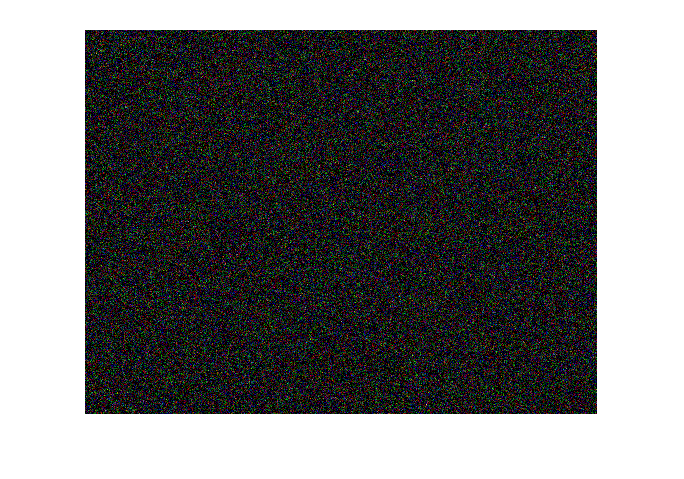

imshow(noise)

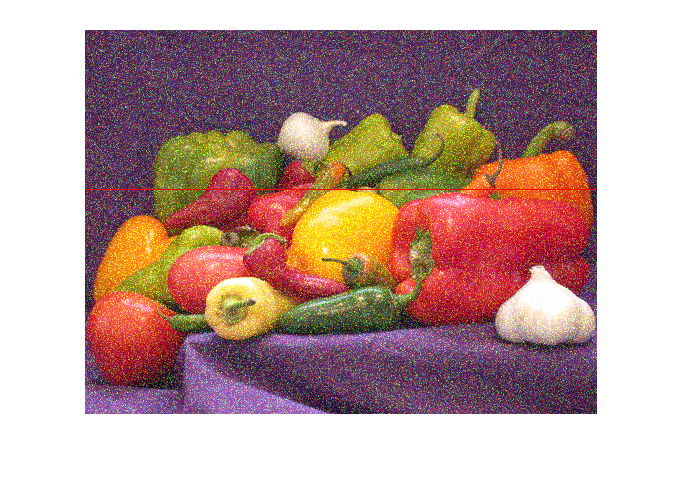

output=im+noise;
imshow(output)
line([1 512],[160 160],'color','r')

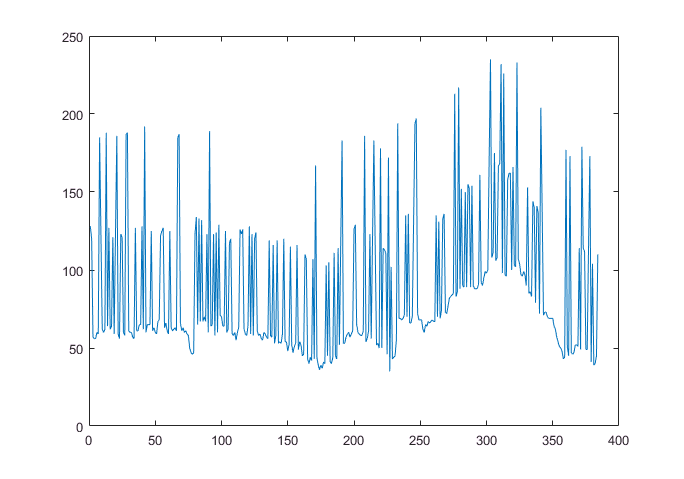

% plot on the red layer
plot(output(:,512,1))

Generate gaussian noise v2:

randn generates a random number with mean 0 and standart deviation of 1, according to gaussian distribution, numbers close to 0 are most likely than numbers far away from zero

dimensions can be passed as aguments:

randn

ans = 0.8273

randn(3)

ans =    -1.0662    0.2642   -0.1484
   -0.0930    0.2714    0.1589
   -1.2706   -0.7039   -0.6778


randn([3 5])

ans =     0.4463   -0.8953    1.3450    0.9527   -0.2943
    0.1071    1.2325    1.9869    1.9020   -0.2445
    0.1964   -0.3880   -1.2866    1.0643   -0.9462


**Generate** **Gaussian Distribution:**

generate a noise array with 100 elements and create a histrogram from that, also passing our bin centers. hist returns [n, x], where n is number of points and x are bin centers. linspace(left,right,count)  generates *count* elements, equally distributed from *left* to *right* inclusive.

Resulting plot will be something similiar to the Gaussian distribution

disp('Generate Gaussian Distribution')

Generate Gaussian Distribution


noise = randn([1 100]);
[n, x]=hist(noise,linspace(-3,3,7));
% tabular display
[x;n]

ans =     -3    -2    -1     0     1     2     3
     1     5    29    34    24     7     0


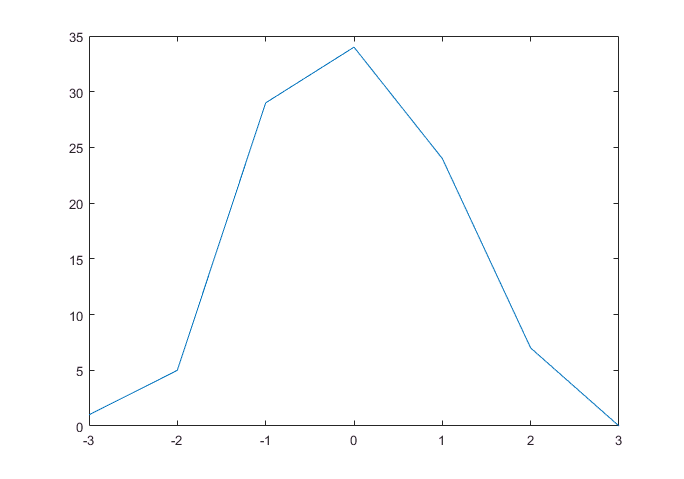

% plot
plot(x, n);

**Other Random functions**

randn - generates normally distributed random value with mean=0 and st. dev=1

rand - generates uniformly distributed random values

randi - generates random integers

**Apply a Gaussian noise to an image:**

disp('Apply a Gaussian noise to an image')

Apply a Gaussian noise to an image


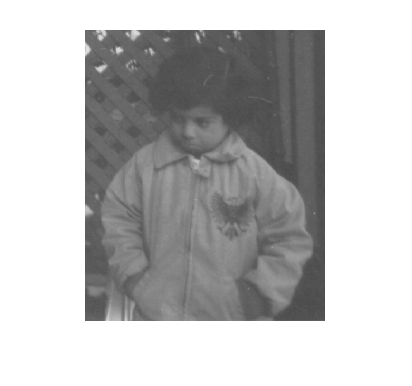

img = imread('pout.tif');
imshow(img)

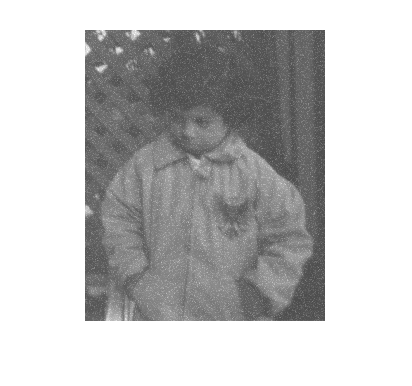

sigma=16;
noise = uint8(randn(size(img)).*sigma);
% add noise image to the original
output=img+noise;
imshow(output)

**Displaying images in Matlab**

*imshow(im, [LOW HIGH])* will display the image *im* with value LOW as black and HIGH as white

*imshow(im, []) *will calculate LOW and HIGH automatically

this is used if you have an image, where intensities range, for example, from o to 1 and etc...

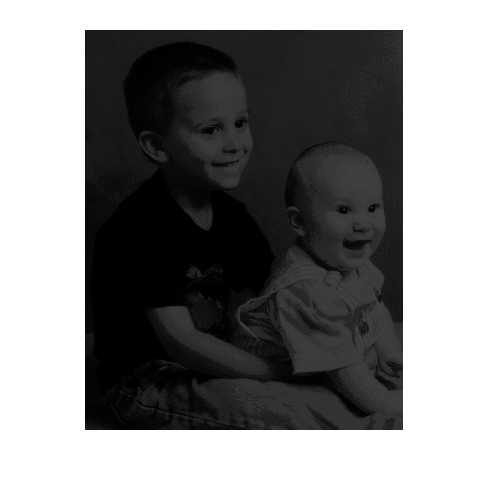

im = imread('kids.tif');

imshow(im)

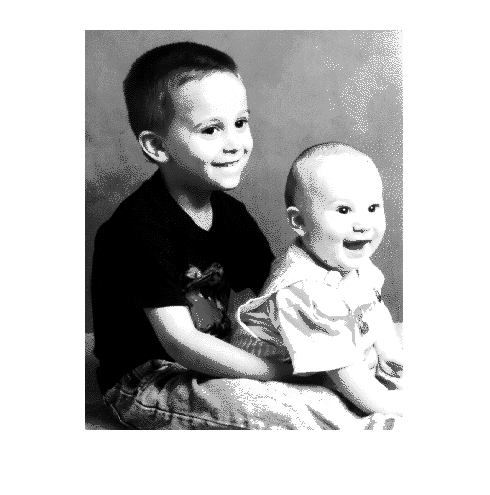

imshow(im,[0 50])

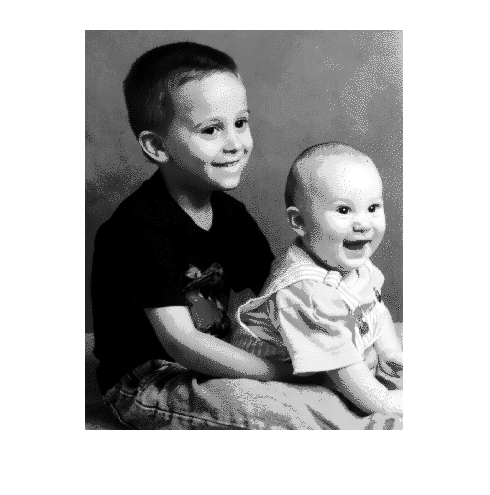

imshow(im,[])